# Deep Learning Bearing Fault diagnosis

clc; close all; clear all;

## Step 1: Data Load

% For 1D - CNN , CNN - LSTM
% [data, label] = data_load("10Class_CWRU");

% For 2D - CNN
imds =imageDatastore('../Fault Dignosis/data/pre_data/CWRU_image_data', 'IncludeSubfolders',true,'LabelSource', 'foldernames');


## Step 2: Data Split

7:3

% For 1D - CNN , CNN - LSTM
% [train,train_label,test,test_label] = data_split(data,label);

% For 2D - CNN
[train,test] = splitEachLabel(imds,0.7,'randomized');

## Step 3: Select DeepLearning Layer

layer = layer("CNN_2D",10);   % Choose layer and the number of output
analyzeNetwork(layer)         % Analyze Deeplearning layers

## Step 4: Hyperparameter setting

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ExecutionEnvironment', 'gpu' ...
    );

## Step 5: Training

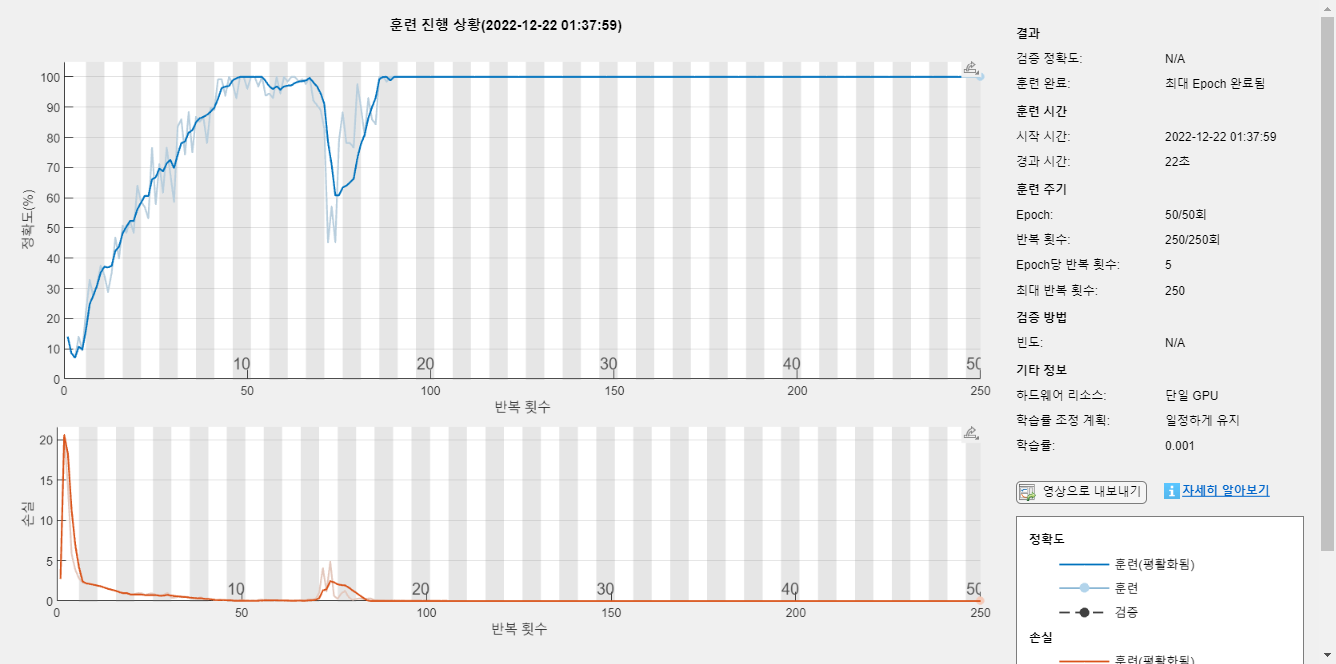

model =   SeriesNetwork - 속성 있음:

         Layers: [20×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% For 1D - CNN , CNN - LSTM
% model = trainNetwork(train,train_label,layer,options)

% For 2D - CNN
model = trainNetwork(train,layer,options)

## Step 6: Result Analysis

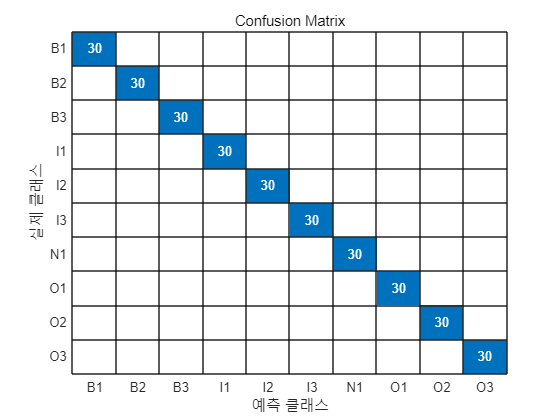

table1 = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy             1        
    Precision            1        
    Recall               1        
    F1_score             1        


table2 = 10×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         


table1 = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy             1        
    Precision            1        
    Recall               1        
    F1_score             1        


table2 = 10×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         
            1                     1                     1         


% For 1D - CNN , CNN - LSTM 
% YPredicted = classify(model,test);
% fig = figure;
% cm = confusionchart(test_label,YPredicted);
% cm.Title = 'Confusion Matrix';
% [table1, table2]=Evaluation_ConfMat(cm)

% For 2D - CNN
YPredicted = classify(model,test);
fig = figure;
cm = confusionchart(test.Labels,YPredicted);
cm.Title = 'Confusion Matrix';

[table1, table2]=Evaluation_ConfMat(cm)